useSim = true;
if useSim
    neatov2.connect();
    f = figure;
else
    % don't forget to change the IP address
    neatov2.connect('192.168.16.75');
end

Deleting previous Neato connection.
Connecting to the Neato.


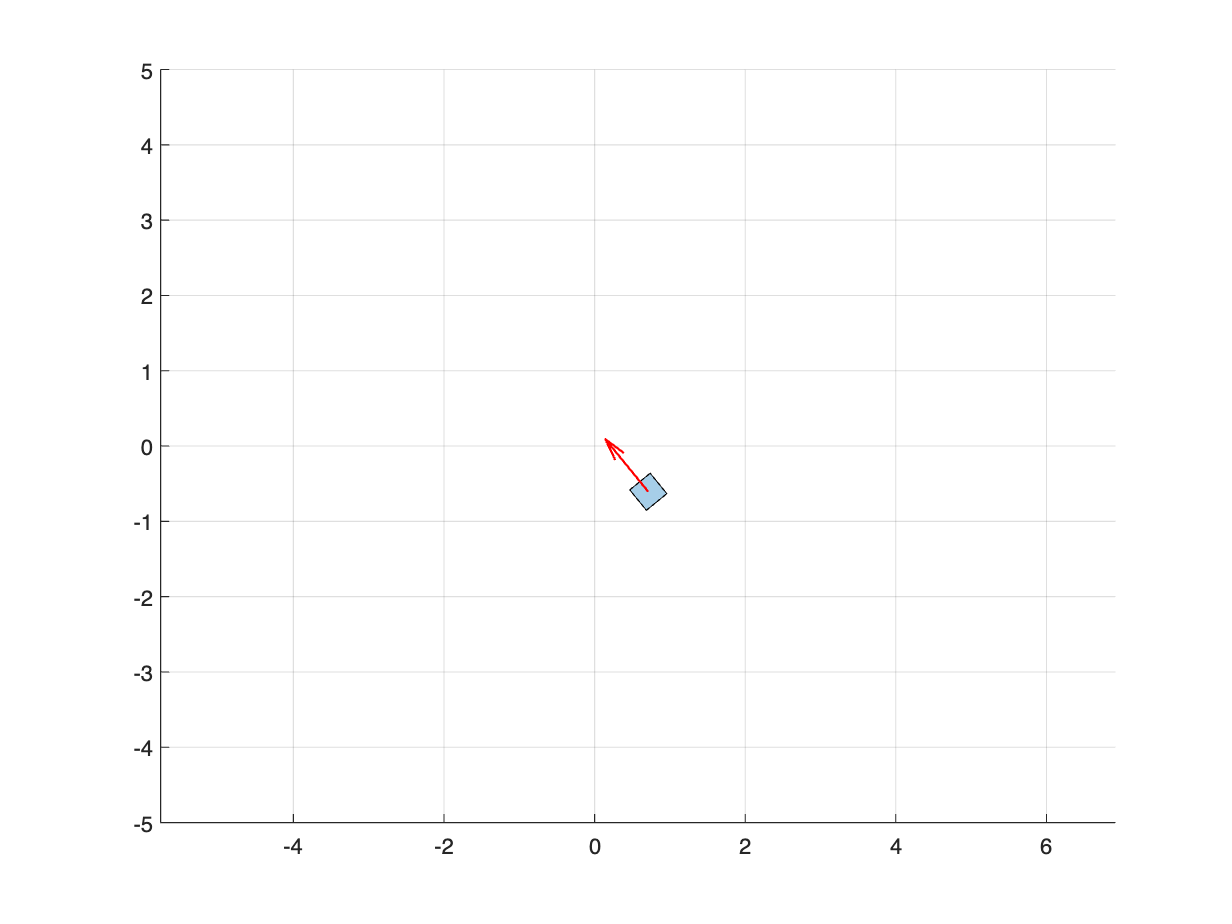


tic;
elapsed = toc;
encoders = zeros(0,3);
while elapsed < 15
    elapsed = toc;
    % in the new code, you have to explicitly send the velocities to the
    % Neato (insead of just putting the velocities in the ``vels`` var)
    if elapsed < 5
        neatov2.setVelocities(0.2, 0.2);
    else
        neatov2.setVelocities(0.2, 0.1);
    end
    % in the new code you have to call receive in order to get sensor data
    % and to allow the simulator to update its state
    sensors = neatov2.receive();
    encoders(end+1,:) = [elapsed, sensors.encoders(1), sensors.encoders(2)];
    if useSim
        % in the new code you have to explicitly plot the simulated robot
        % (this makes it so you don't interfere with any plots you might
        % have created)
        neatov2.plotSim();
    end
    pause(0.01);
end

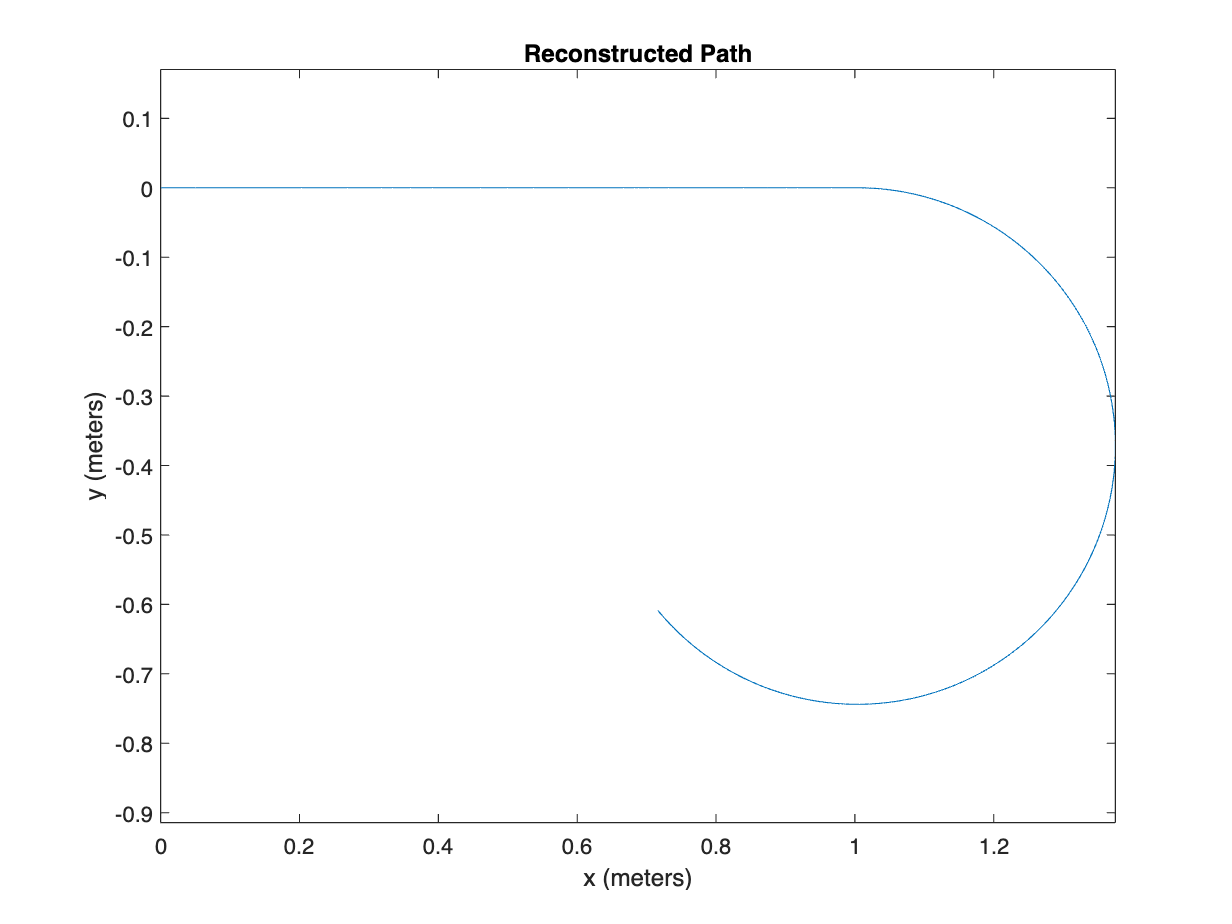

neatov2.setVelocities(0.0, 0.0);

x = 0.0;
y = 0.0;
theta = 0.0;

d = 0.248;
path = zeros(size(encoders,1),3);
path(1,:) = [x y theta];
encoderDiffs = diff(encoders);
for i=1:size(encoderDiffs,1)
    XL = encoderDiffs(i,2);
    XR = encoderDiffs(i,3);
    XN = (XL + XR)/2;
    deltaTheta = (XR - XL)/d;
    x = x + cos(theta)*XN;
    y = y + sin(theta)*XN;
    theta = theta + deltaTheta;
    path(i+1,:) = [x y theta];
end
figure;
plot(path(:,1), path(:,2));
title('Reconstructed Path');
axis equal;
xlabel("x (meters)");
ylabel("y (meters)");